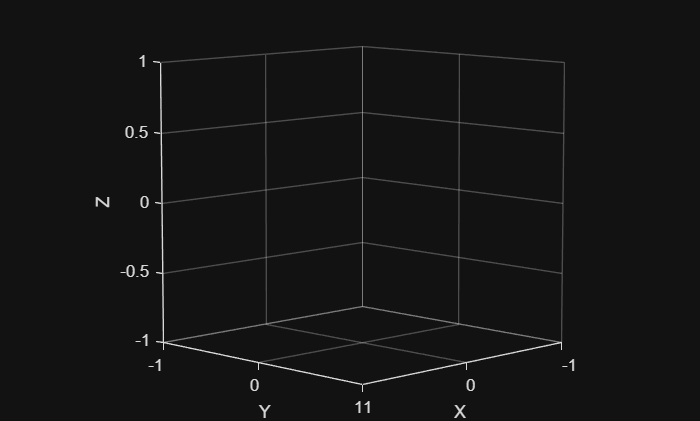

   Robot Base Name: base_link


   Number of Bodies: 12


   Number of Joints: 12


   Data Format: struct



┌────┬─────────────────────┬─────────────┬──────────────────────┬─────────────────┐


│ #  │ Joint Name          │ Type        │ Home Position        │ Limits [rad]    │


├────┼─────────────────────┼─────────────┼──────────────────────┼─────────────────┤


│ 1  │ shoulder_joint1     │ revolute    │   0.0000 rad (  0.00°) │ [  -Inf,    Inf] │
│ 2  │ shoulder_joint2     │ revolute    │   0.0000 rad (  0.00°) │ [ -1.57,   1.57] │
│ 3  │ elbow_joint         │ revolute    │   0.0000 rad (  0.00°) │ [ -1.57,   1.57] │
│ 4  │ wrist_turn_joint    │ revolute    │   0.0000 rad (  0.00°) │ [  -Inf,    Inf] │
│ 5  │ wrist_tilt_joint    │ revolute    │   0.0000 rad (  0.00°) │ [ -2.09,   1.57] │
│ 6  │ gripper_turn_joint  │ revolute    │   0.0000 rad (  0.00°) │ [  -Inf,    Inf] │
│ 7  │ gripper_left_drive_arm_joint │ revolute    │   0.0000 rad (  0.00°) │ [-15708.00, 15708.00] │
│ 8  │ gripper_left_finger_joint │ revolute    │   0.0000 rad (  0.00°) │ [-15708.00, 15708.00] │
│ 9  │ gripper_left_support_arm_joint │ revolute    │   0.0000 rad (  0.00°) │ [  0.00,   0.00] │
│ 10 │ gripper_right_drive_arm_joint │ revolute    │   0.0000 rad (  0.00°) │ [-15708.00, 15708.00] │
│ 11 │ gripper_right_finger_joint │ revolute    │   0.0000 rad (  0.00°) │ [-15

Endefffector: gripper_right_support_arm_link


   X = 0.0414 m


   Y = 0.3578 m


   Z = 0.3602 m


   Distance from base: 0.5094 m


%first test file to get to know the robotics systems toolbox
%Author: Matteo Gassler
%02.02.2026

clear; close all; clc;


% where the urdf and meshes are located, change to your location
try
    urdfFile = 'C:\Users\matte\Documents\Open-robot-arm\Software\robotarm\urdf\robot_armV2.SLDASM.urdf';
    meshPath = 'C:\Users\matte\Documents\Open-robot-arm\Software\robotarm\meshes';
catch ME
    fprintf("Error:")
    disp(ME.identifier)
end


robot = importrobot(urdfFile, 'MeshPath', meshPath);
homeConfig = homeConfiguration(robot);


% Create IK solver 
ik = inverseKinematics('RigidBodyTree', robot);

% Define target position
targetX = input("Input your desired x coordinates in m:");
targetY = input("Input your desired y coordinates in m:");
targetZ = input("Input your desired z coordinates in m:");

fprintf('Target position: [%.3f, %.3f, %.3f] m\n', targetX, targetY, targetZ);

% Create target pose turns the vector into a goal matrix
targetPose = trvec2tform([targetX, targetY, targetZ]);

% Set priority, first 3 position, secound 3 orientatien(position is more important than orientation)
weights = [1, 1, 1, 0.1, 0.1, 0.1];

% Initial guess
initialGuess = homeConfiguration(robot);

endEffectorName = robot.Bodies{end}.Name;

% Solve IK 
[configSolution, solnInfo] = ik(endEffectorName, targetPose, weights, initialGuess);

% Check result
if strcmp(solnInfo.Status, 'success')
    fprintf('✓ IK solution found!\n\n');
    
    % Print joint angles
    fprintf('Joint Angles:\n');
    for i = 1:numel(configSolution)
        fprintf('  Joint %d: %.4f rad (%.2f°)\n', ...
            i, configSolution(i).JointPosition, rad2deg(configSolution(i).JointPosition));
    end
    fprintf('\n');
    
    % Verify with FK (built-in)
    transform = getTransform(robot, configSolution, endEffectorName);
    actualPosition = tform2trvec(transform);
    
    fprintf('Verification (Forward Kinematics):\n');
    fprintf('  Target:  [%.4f, %.4f, %.4f] m\n', targetX, targetY, targetZ);
    fprintf('  Actual:  [%.4f, %.4f, %.4f] m\n', actualPosition(1), actualPosition(2), actualPosition(3));
    fprintf('  Error:   [%.4f, %.4f, %.4f] m\n\n', ...
        abs(targetX-actualPosition(1)), abs(targetY-actualPosition(2)), abs(targetZ-actualPosition(3)));
    
    % Visualize
    figure;
    show(robot, configSolution);
    title(sprintf('Robot reaching [%.2f, %.2f, %.2f]', targetX, targetY, targetZ));
    xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
    grid on;
    view(45, 30);
    
else
    fprintf('✗ IK solution NOT found!\n');
    fprintf('Target may be out of reach.\n');
end
%information about the robot
fprintf('   Robot Base Name: %s\n', robot.BaseName);
fprintf('   Number of Bodies: %d\n', numel(robot.Bodies));
fprintf('   Number of Joints: %d\n', numel(robot.Bodies));
fprintf('   Data Format: %s\n\n', robot.DataFormat);

